clc
clear all
close all
rng(0)

%x0 = [1;1;1;1;1]
n = 5

n = 5

x0 =rand(n,1)

x0 =     0.8147
    0.9058
    0.1270
    0.9134
    0.6324


x0_mean = mean(x0)

x0_mean = 0.6786

K = 100

K = 100

% A primitive
A = [
    [0.5,0.5,0,0,0];
    [0,0,1,0,0];
    [0,0,0,1,0];
    [0,0,0,0,1];
    [1,0,0,0,0];
    ];
G = digraph(A)

G =   digraph with properties:

    Edges: [6×2 table]
    Nodes: [5×0 table]


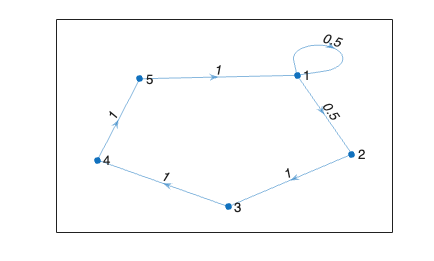

p = plot(G, 'Layout', 'force');
p.EdgeLabel = G.Edges.Weight;


x_inf = Simulate_Consensus(A ,A,x0, K, 'sync')

x_inf =     0.7013
    0.7013
    0.7013
    0.7013
    0.7013


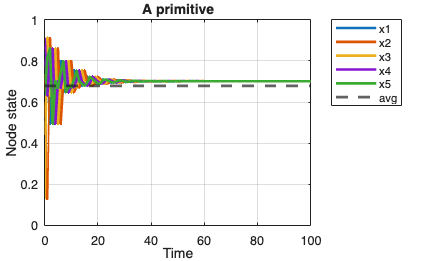

X = Simulate_Trajectory(A, A, x0, K, 'sync');

figure;
plot(0:K, X', 'LineWidth', 2);  % linee più spesse
yline(x0_mean, '--', 'LineWidth', 2);  % linea tratteggiata
grid on;
title('A primitive')
xlabel('Time');
ylabel('Node state');
legend('x1', 'x2', 'x3', 'x4', 'x5','avg','Location', 'northeastoutside');

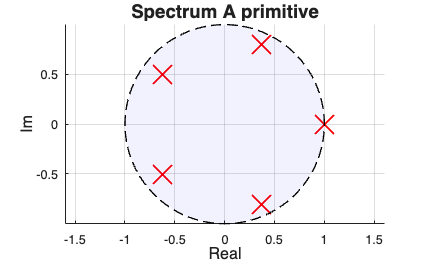


figure;
autovalori = eig(A);
real_part = real(eig(A));
imag_part = imag(eig(A));
hold on;
plot(real_part, imag_part, 'rx', 'MarkerSize', 20, 'LineWidth', 1.5);
title('Spectrum A primitive', 'FontSize', 14);
xlabel('Real', 'FontSize', 12);
ylabel('Im', 'FontSize', 12);

theta = linspace(0, 2*pi, 200);
x_circle = cos(theta);
y_circle = sin(theta);
fill(x_circle, y_circle, 'b', 'FaceAlpha', 0.05, ...
     'EdgeColor', 'k', 'LineStyle', '--', 'LineWidth', 1);
axis equal;

grid on;
hold off;


fprintf('\n--- Lista degli Autovalori ---\n');


--- Lista degli Autovalori ---


for i = 1:length(autovalori)
    if imag(autovalori(i)) >= 0
        fprintf('λ_%d = %8.4f + %8.4fi\n', i, real(autovalori(i)), imag(autovalori(i)));
    else
        fprintf('λ_%d = %8.4f - %8.4fi\n', i, real(autovalori(i)), abs(imag(autovalori(i))));
    end
end

λ_1 =   1.0000 +   0.0000i
λ_2 =   0.3710 +   0.8038i


λ_3 =   0.3710 -   0.8038i


λ_4 =  -0.6210 +   0.5023i


λ_5 =  -0.6210 -   0.5023i


fprintf('------------------------------\n');

------------------------------


% A irr but not primitive
A = [
    [0,1,0,0,0];
    [0,0,1,0,0];
    [0,0,0,1,0];
    [0,0,0,0,1];
    [1,0,0,0,0];
    ];
G = digraph(A)

G =   digraph with properties:

    Edges: [5×2 table]
    Nodes: [5×0 table]


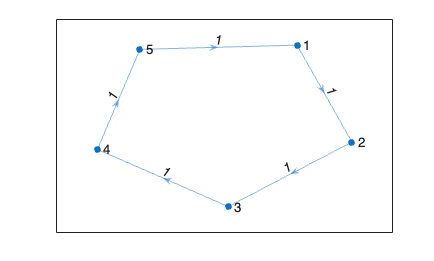

p = plot(G, 'Layout', 'force');
p.EdgeLabel = G.Edges.Weight;


K = 15;

x_inf = Simulate_Consensus(A ,A,x0, K, 'sync')

x_inf =     0.8147
    0.9058
    0.1270
    0.9134
    0.6324


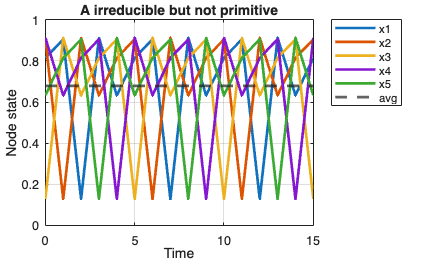

X = Simulate_Trajectory(A, A, x0, K, 'sync');

figure;
plot(0:K, X', 'LineWidth', 2);  % linee più spesse
yline(x0_mean, '--', 'LineWidth', 2);  % linea tratteggiata
grid on;
title('A irreducible but not primitive')
xlabel('Time');
ylabel('Node state');
legend('x1', 'x2', 'x3', 'x4', 'x5','avg','Location', 'northeastoutside');

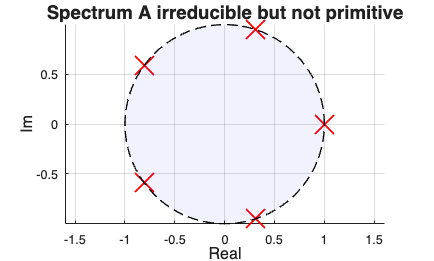


figure;
autovalori = eig(A);
real_part = real(eig(A));
imag_part = imag(eig(A));
hold on;
plot(real_part, imag_part, 'rx', 'MarkerSize', 20, 'LineWidth', 1.5);
title('Spectrum A irreducible but not primitive', 'FontSize', 14);
xlabel('Real', 'FontSize', 12);
ylabel('Im', 'FontSize', 12);

theta = linspace(0, 2*pi, 200);
x_circle = cos(theta);
y_circle = sin(theta);
fill(x_circle, y_circle, 'b', 'FaceAlpha', 0.05, ...
     'EdgeColor', 'k', 'LineStyle', '--', 'LineWidth', 1);
axis equal;

grid on;
hold off;


fprintf('\n--- Lista degli Autovalori ---\n');


--- Lista degli Autovalori ---


for i = 1:length(autovalori)
    if imag(autovalori(i)) >= 0
        fprintf('λ_%d = %8.4f + %8.4fi\n', i, real(autovalori(i)), imag(autovalori(i)));
    else
        fprintf('λ_%d = %8.4f - %8.4fi\n', i, real(autovalori(i)), abs(imag(autovalori(i))));
    end
end

λ_1 =  -0.8090 +   0.5878i


λ_2 =  -0.8090 -   0.5878i


λ_3 =   0.3090 +   0.9511i


λ_4 =   0.3090 -   0.9511i


λ_5 =   1.0000 +   0.0000i


fprintf('------------------------------\n');

------------------------------


%Asymptotic consensous
K = 30;
A = [
    0, 1, 0, 0, 0;  % 1 va a 2
    0, 0, 1, 0, 0;  % 2 va a 3
    0, 0, 0, 1, 0;  % 3 va a 4
    0, 0, 0, 0, 1;  % 4 va a 5
    0, 0, 0, 0, 1;  % 5 va a se stesso (POZZO APERIODICO)
    ];
G = digraph(A)

G =   digraph with properties:

    Edges: [5×2 table]
    Nodes: [5×0 table]


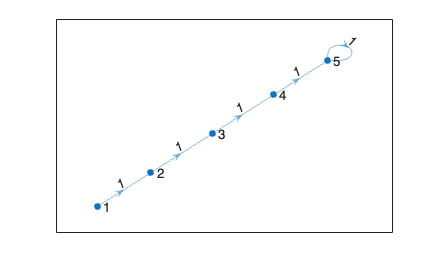

p = plot(G, 'Layout', 'force');
p.EdgeLabel = G.Edges.Weight;


x_inf = Simulate_Consensus(A ,A,x0, K, 'sync')

x_inf =     0.6324
    0.6324
    0.6324
    0.6324
    0.6324


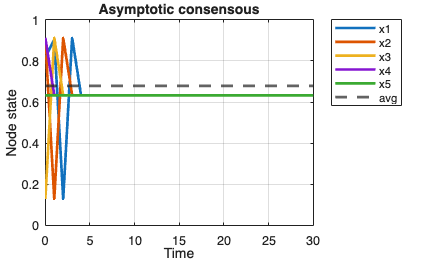

X = Simulate_Trajectory(A, A, x0, K, 'sync');

figure;
plot(0:K, X', 'LineWidth', 2);  % linee più spesse
yline(x0_mean, '--', 'LineWidth', 2);  % linea tratteggiata
grid on;
title('Asymptotic consensous')
xlabel('Time');
ylabel('Node state');
legend('x1', 'x2', 'x3', 'x4', 'x5','avg','Location', 'northeastoutside');

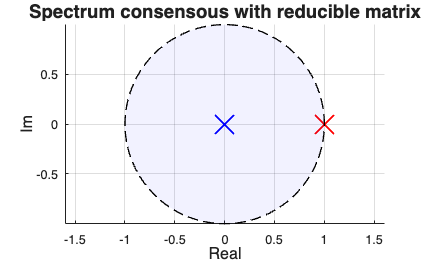


figure;
autovalori = eig(A);
real_part = real(eig(A));
imag_part = imag(eig(A));
hold on;
plot(real_part(1:4), imag_part(1:4), 'bx', 'MarkerSize', 20, 'LineWidth', 1.5);
plot(real_part(end), imag_part(end), 'rx', 'MarkerSize', 20, 'LineWidth', 1.5);
title('Spectrum consensous with reducible matrix', 'FontSize', 14);
xlabel('Real', 'FontSize', 12);
ylabel('Im', 'FontSize', 12);

theta = linspace(0, 2*pi, 200);
x_circle = cos(theta);
y_circle = sin(theta);
fill(x_circle, y_circle, 'b', 'FaceAlpha', 0.05, ...
     'EdgeColor', 'k', 'LineStyle', '--', 'LineWidth', 1);
axis equal;

grid on;
hold off;


fprintf('\n--- Lista degli Autovalori ---\n');


--- Lista degli Autovalori ---


for i = 1:length(autovalori)
    if imag(autovalori(i)) >= 0
        fprintf('λ_%d = %8.4f + %8.4fi\n', i, real(autovalori(i)), imag(autovalori(i)));
    else
        fprintf('λ_%d = %8.4f - %8.4fi\n', i, real(autovalori(i)), abs(imag(autovalori(i))));
    end
end

λ_1 =   0.0000 +   0.0000i
λ_2 =   0.0000 +   0.0000i
λ_3 =   0.0000 +   0.0000i
λ_4 =   0.0000 +   0.0000i
λ_5 =   1.0000 +   0.0000i


fprintf('------------------------------\n');

------------------------------


% asymptotic disagreement
K = 30;
A = [
    [0,0.5,0,0.5,0];
    [0,0,1,0,0];
    [0,0.5,0.5,0,0];
    [0,0,0,0,1];
    [0,0,0,0.5,0.5];
    ];
G = digraph(A)

G =   digraph with properties:

    Edges: [8×2 table]
    Nodes: [5×0 table]


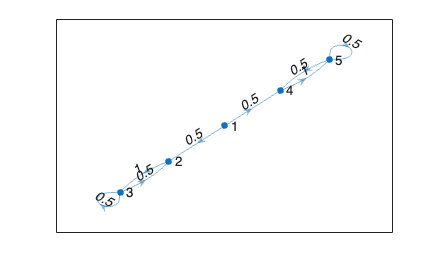

p = plot(G, 'Layout', 'force');
p.EdgeLabel = G.Edges.Weight;


x_inf = Simulate_Consensus(A ,A,x0, K, 'sync')

x_inf =     0.5563
    0.3866
    0.3866
    0.7260
    0.7260


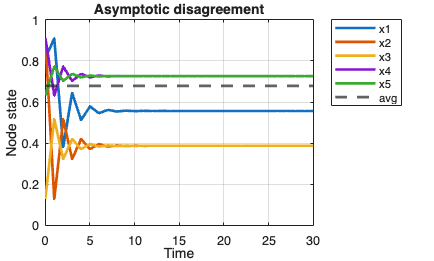

X = Simulate_Trajectory(A, A, x0, K, 'sync');

figure;
plot(0:K, X', 'LineWidth', 2);  % linee più spesse
yline(x0_mean, '--', 'LineWidth', 2);  % linea tratteggiata
grid on;
title('Asymptotic disagreement')
xlabel('Time');
ylabel('Node state');
legend('x1', 'x2', 'x3', 'x4', 'x5','avg','Location', 'northeastoutside');

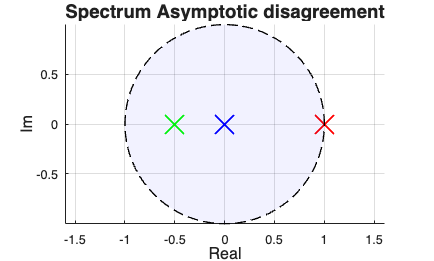


figure;
autovalori = sort(eig(A));
real_part = real(autovalori);
imag_part = imag(autovalori);
hold on;
plot(real_part(1:2), imag_part(1:2), 'gx', 'MarkerSize', 20, 'LineWidth', 1.5);
plot(real_part(3:4), imag_part(3:4), 'bx', 'MarkerSize', 20, 'LineWidth', 1.5);
plot(real_part(4:5), imag_part(4:5), 'rx', 'MarkerSize', 20, 'LineWidth', 1.5);
title('Spectrum Asymptotic disagreement', 'FontSize', 14);
xlabel('Real', 'FontSize', 12);
ylabel('Im', 'FontSize', 12);

theta = linspace(0, 2*pi, 200);
x_circle = cos(theta);
y_circle = sin(theta);
fill(x_circle, y_circle, 'b', 'FaceAlpha', 0.05, ...
     'EdgeColor', 'k', 'LineStyle', '--', 'LineWidth', 1);
axis equal;

grid on;
hold off;


autovalori = eig(A);
fprintf('\n--- Lista degli Autovalori ---\n');


--- Lista degli Autovalori ---


for i = 1:length(autovalori)
    if imag(autovalori(i)) >= 0
        fprintf('λ_%d = %8.4f + %8.4fi\n', i, real(autovalori(i)), imag(autovalori(i)));
    else
        fprintf('λ_%d = %8.4f - %8.4fi\n', i, real(autovalori(i)), abs(imag(autovalori(i))));
    end
end

λ_1 =   0.0000 +   0.0000i
λ_2 =  -0.5000 +   0.0000i
λ_3 =   1.0000 +   0.0000i
λ_4 =  -0.5000 +   0.0000i
λ_5 =   1.0000 +   0.0000i


fprintf('------------------------------\n');

------------------------------


% not converging
K = 30;
A = [
    [0,0.5,0,0.5,0];
    [0,0,1,0,0];
    [0,1,0,0,0];
    [0,0,0,0,1];
    [0,0,0,0.5,0.5];
    ];
G = digraph(A)

G =   digraph with properties:

    Edges: [7×2 table]
    Nodes: [5×0 table]


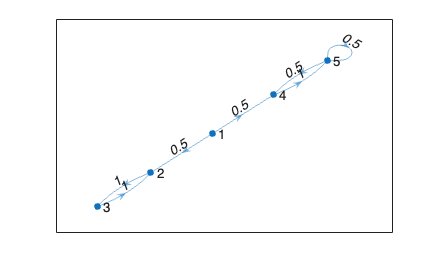

p = plot(G, 'Layout', 'force');
p.EdgeLabel = G.Edges.Weight;


x_inf = Simulate_Consensus(A ,A,x0, K, 'sync')

x_inf =     0.4265
    0.9058
    0.1270
    0.7260
    0.7260


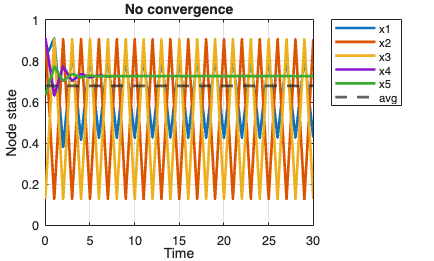

X = Simulate_Trajectory(A, A, x0, K, 'sync');

figure;
plot(0:K, X', 'LineWidth', 2);  % linee più spesse
yline(x0_mean, '--', 'LineWidth', 2);  % linea tratteggiata
grid on;
title('No convergence')
xlabel('Time');
ylabel('Node state');
legend('x1', 'x2', 'x3', 'x4', 'x5','avg','Location', 'northeastoutside');

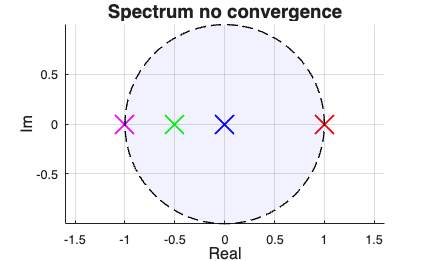


figure;
autovalori = sort(eig(A));
real_part = real(autovalori);
imag_part = imag(autovalori);
hold on;
plot(real_part(1), imag_part(1), 'mx', 'MarkerSize', 20, 'LineWidth', 1.5);
plot(real_part(2), imag_part(2), 'gx', 'MarkerSize', 20, 'LineWidth', 1.5);
plot(real_part(3:4), imag_part(3:4), 'bx', 'MarkerSize', 20, 'LineWidth', 1.5);
plot(real_part(4:5), imag_part(4:5), 'rx', 'MarkerSize', 20, 'LineWidth', 1.5);
title('Spectrum no convergence', 'FontSize', 14);
xlabel('Real', 'FontSize', 12);
ylabel('Im', 'FontSize', 12);

theta = linspace(0, 2*pi, 200);
x_circle = cos(theta);
y_circle = sin(theta);
fill(x_circle, y_circle, 'b', 'FaceAlpha', 0.05, ...
     'EdgeColor', 'k', 'LineStyle', '--', 'LineWidth', 1);
axis equal;

grid on;
hold off;

autovalori = eig(A);

fprintf('\n--- Lista degli Autovalori ---\n');


--- Lista degli Autovalori ---


for i = 1:length(autovalori)
    if imag(autovalori(i)) >= 0
        fprintf('λ_%d = %8.4f + %8.4fi\n', i, real(autovalori(i)), imag(autovalori(i)));
    else
        fprintf('λ_%d = %8.4f - %8.4fi\n', i, real(autovalori(i)), abs(imag(autovalori(i))));
    end
end

λ_1 =   0.0000 +   0.0000i
λ_2 =   1.0000 +   0.0000i
λ_3 =  -1.0000 +   0.0000i
λ_4 =  -0.5000 +   0.0000i
λ_5 =   1.0000 +   0.0000i


fprintf('------------------------------\n');

------------------------------
